# Lattice Modulation, Scan Force

## Set atom and magnetic field

% atom
atom = Alkali("Lithium7");

% B field
bList = num2cell(linspace(1.20e-2,1.205e-2,200));
niB = 543.6e-4; %non-interacting feshbach field
bField = cellfun(@(x) MagneticField(...
    bias = [0;0;niB],...
    gradient = [0,0,0;0,0,0;0,x,0]),bList,'UniformOutput',false);

## Set benchmark simulation

% set laser
laser = GaussianBeam( ...
    wavelength = 1064e-9,...
    direction = [0;1;0],...
    polarization = [0;0;1],...
    power = 0.6, ...
    waist = 110e-6 ...
    );
laser = {laser};

% set optical lattice
ol = OpticalLattice(atom,laser{1});
ol.DepthSpec = 5.9637 * ol.RecoilEnergy;
ol.updateIntensity;
kL = ol.Laser.AngularWavenumber;
laser = {ol.Laser};


% set modulation
pulse1 = TanhSinePulse( ...
    amplitude=0.068 * 2, ...
    duration=1.1111e-3, ...
    frequency=75.2639e3, ...
    startTime=0,...
    riseTime=0.1e-3,...
    fallTime = 0.1e-3);
pulse2 = TanhSinePulse( ...
    amplitude=0.068 * 2, ...
    duration=1.1111e-3, ...
    frequency=75.2639e3, ...
    startTime=17.77778e-3,...
    riseTime=0.1e-3,...
    fallTime = 0.1e-3);
latticeMod = WaveformList("LatticeMod");
latticeMod.WaveformOrigin = {pulse1,pulse2};
latticeMod.ConcatMethod = "Simultaneous";
% latticeMod.SamplingRate = 10e6;
latticeMod = {latticeMod};

% Initial condition
ic = InitialCondition("LatticeFourierSeSim1D");

ans =   DynamicProperty with properties:

                    Name: 'QuasiMomentum'
             Description: ''
     DetailedDescription: ''
               GetAccess: 'public'
               SetAccess: 'public'
               Dependent: 0
                Constant: 0
                Abstract: 0
               Transient: 0
                  Hidden: 0
           GetObservable: 0
           SetObservable: 0
                AbortSet: 0
             NonCopyable: 1
    PartialMatchPriority: 1
               GetMethod: []
               SetMethod: []
              HasDefault: 0
              Validation: [0×0 meta.Validation]
           DefiningClass: [0×0 meta.class]


ic.QuasiMomentum = 0.3 * kL;
[~,ic.WaveFunction] = ol.computeBand1D(ic.QuasiMomentum,1);


se = LatticeFourierSeSim1D("Test", ...
    laser = laser,...
    magneticField = bField,...
    latticeModulation = latticeMod,...
    timeStep=1e-7,...
    totalTime=19e-3,...
    initialCondition = ic,...
    stateIndex = 6);

Constructing the object.
Setting up folders.
Creating a database entry.
Updating the object file.



se.start

Updating the object file.


Updating the object file.
Updating the object file.


Updating the object file.
Updating the object file.
Python Error: OperationalError: no such table: hfsDataAB
> In parallel.internal.pool.optionallyDeserialize (line 7)
In parallel.internal.parfor.cppRemoteParallelFunc

Updating the object file.
Updating the object file.
Python Error: OperationalError: no such table: literatureDME
> In parallel.internal.pool.optionallyDeserialize (line 7)
In parallel.internal.parfor.cppRemoteParallelFunction (

Updating the object file.
Updating the object file.
Updating the object file.
Updating the object file.
All runs are completed.
Updating the object file.


## Plot Fringe

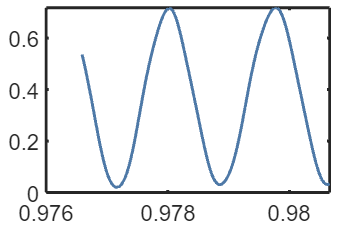

% plot benchmark
trialNumber = 20;
obj = loadTrial(createReader("simulation"),"lattice_fourier_simulation_1d",trialNumber);
data = obj.readBand(1);

mp = MagneticPotential(atom,bField{1});
stateIdx = mp.StateIndex;
stateList = atom.(mp.Manifold).StateList;
mJ = stateList.MJ(stateIdx);
gJ = stateList.gJ(stateIdx);
mI = stateList.MI(stateIdx);
gI = stateList.gI(stateIdx);
muB = Constants.SI("muB");
h = Constants.SI("hbar") * 2 * pi;
hbar = Constants.SI("hbar");
prefactor = (mJ * gJ + mI * gI) * muB / h;
FList0 = abs(h * prefactor * cell2mat(bList));
g = 9.81;
M = atom.mass;
figure(11240)
plot(FList0/M/g,data)
xlabel("$F/Mg$")
ylabel("$D$ Band Fraction")
render

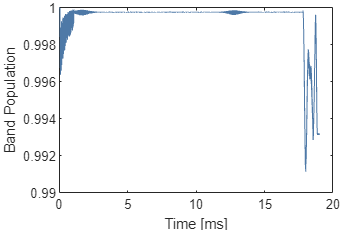

trialNumber = 18;
obj = loadTrial(createReader("simulation"),"lattice_fourier_simulation_1d",trialNumber);
obj.SimRun(100).plotBand(1)